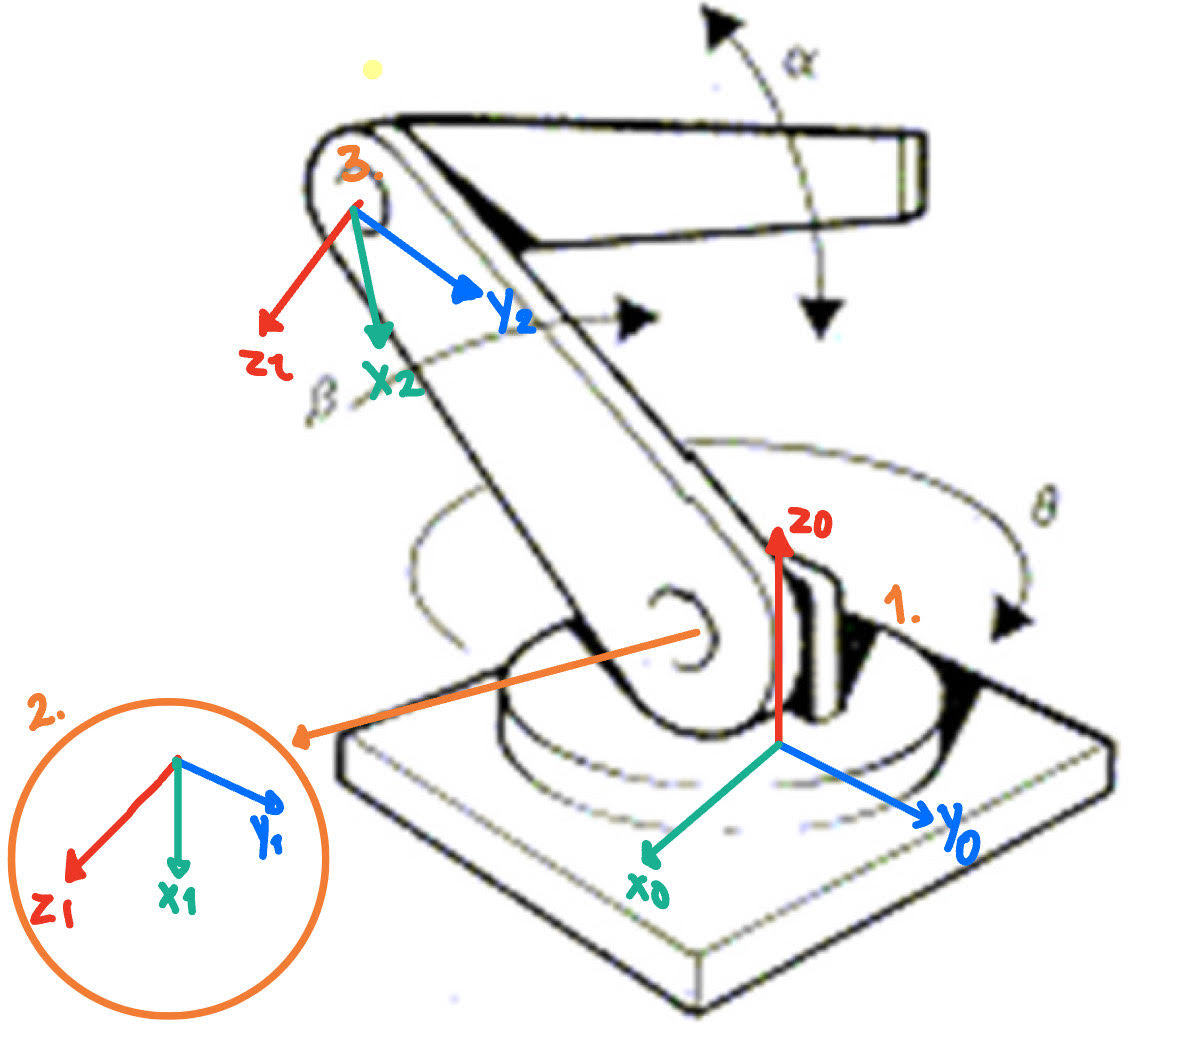

# **Actividad 4. Análisis Genera**

## Sección 1: Limpieza de entorno, variables simbólicas y configuración básica

- Se limpian las variables y se cierran ventanas (`clear all`, `close all`, `clc`) para comenzar con un entorno limpio en MATLAB.

- Se declaran las variables simbólicas para las articulaciones (`th1`, `th2`, `th3`) y las longitudes (`l1`, `l2`, `l3`).

- Se define que el robot tiene tres juntas rotacionales, asignando el vector `RP=[0 0 0]` (0 = rotacional).

- Se construyen los vectores de coordenadas articulares `Q` y de velocidades `Qp`.

- Se obtiene el número de grados de libertad (`GDL`).

%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas
syms th1(t) th2(t) th3(t) t l1 l2 l3

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0 0];

%Creamos el vector de coordenadas articulares
Q= [th1, th2, th3];
%disp('Coordenadas generalizadas');
%pretty (Q);

%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
%disp('Velocidades generalizadas');
%pretty (Qp);
%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

## Sección 2: Definición de las articulaciones (posiciones y rotaciones)

- Se describe la Articulación 1 con un desplazamiento inicial en Z de l1. Luego, la matriz de rotación se define como la composición Rz(th1)×Ry(90∘)para ubicar correctamente el eje de la segunda articulación.

- En la Articulación 2, se traslada en el plano XY con un radio l2 y ángulo theta_θ2�. Su rotación es Rz(th2

- En la Articulación 3, se repite la idea de la articulación 2 pero con radio l3 y ángulo theta_θ3�.

- Cada articulación es puramente rotacional, por lo que no hay juntas prismáticas en este caso.

%Articulación 1
%Articulación 1 a Articulación 2
%Posición de la articulación 1 a 2
P(:,:,1)= [0;0;l1];
%Matriz de rotación de la junta 1 a 2
R(:,:,1)= rotacion_z(th1)*rotacion_y(90);

%Articulación 2
%Articulación 2 a Articulación 3
%Posición de la articulación 2 a 3
P(:,:,2)= [l2*cos(th2); l2*sin(th2);0];
%Matriz de rotación de la junta 2 a 3
R(:,:,2)=  rotacion_z(th2);

%Articulación 3 
%Posición de la articulación 3 respecto a 2
P(:,:,3)= [l3*cos(th3); l3*sin(th3);0];

%Matriz de rotación de la junta 3 respecto a 2  0º
R(:,:,3)=  rotacion_z(th3)

$$\left(\begin{array}{ccc} 0 & -\sin\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) & \cos\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right)\\ 0 & \cos\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) & \sin\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right)\\ -1 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{ccc} \cos\left(\frac{\pi \,{\mathrm{th}}_{2}\left(t\right)}{180}\right) & -\sin\left(\frac{\pi \,{\mathrm{th}}_{2}\left(t\right)}{180}\right) & 0\\ \sin\left(\frac{\pi \,{\mathrm{th}}_{2}\left(t\right)}{180}\right) & \cos\left(\frac{\pi \,{\mathrm{th}}_{2}\left(t\right)}{180}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{ccc} \cos\left(\frac{\pi \,{\mathrm{th}}_{3}\left(t\right)}{180}\right) & -\sin\left(\frac{\pi \,{\mathrm{th}}_{3}\left(t\right)}{180}\right) & 0\\ \sin\left(\frac{\pi \,{\mathrm{th}}_{3}\left(t\right)}{180}\right) & \cos\left(\frac{\pi \,{\mathrm{th}}_{3}\left(t\right)}{180}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

## Sección 3: Construcción de las matrices de transformación homogénea (locales y globales)

- Se crea un vector de ceros para completar la fila [0  0  0  1]en la matriz de transformación homogénea.

- Se inicializan las matrices locales `A` y globales `T`.

- Se guardan las posiciones `PO` y rotaciones `RO` para el último eslabón.

- En el bucle `for`, se construyen las transformaciones homogéneas globales `T(:,:,i)` multiplicando secuencialmente las matrices.

- Se muestra en pantalla cada `T(:,:,i)` para observar la posición y orientación de cada articulación en el sistema de referencia inercial.

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str))
    T(:,:,i)= simplify(T(:,:,i))
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación global T1


$$\left(\begin{array}{cccc} 0 & -\sin\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) & \cos\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) & 0\\ 0 & \cos\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) & \sin\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) & 0\\ -1 & 0 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccc} \cos\left(\frac{\pi \,{\mathrm{th}}_{3}\left(t\right)}{180}\right) & -\sin\left(\frac{\pi \,{\mathrm{th}}_{3}\left(t\right)}{180}\right) & 0 & l_{3}\,\cos\left({\mathrm{th}}_{3}\left(t\right)\right)\\ \sin\left(\frac{\pi \,{\mathrm{th}}_{3}\left(t\right)}{180}\right) & \cos\left(\frac{\pi \,{\mathrm{th}}_{3}\left(t\right)}{180}\right) & 0 & l_{3}\,\sin\left({\mathrm{th}}_{3}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

/         / pi th1(t) \     / pi th1(t) \     \
|  0, -sin| --------- |, cos| --------- |,  0 |
|         \    180    /     \    180    /     |
|                                             |
|         / pi th1(t) \     / pi th1(t) \     |
|  0,  cos| --------- |, sin| --------- |,  0 |
|         \    180    /     \    180    /     |
|                                             |
| -1,         0,                 0,        l1 |
|                                             |
\  0,         0,                 0,         1 /



Matriz de Transformación global T2


$$\left(\begin{array}{cccc} 0 & -\sin\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) & \cos\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) & 0\\ 0 & \cos\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) & \sin\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) & 0\\ -1 & 0 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\begin{array}{l} \left(\begin{array}{cccc} -\sigma_{1}\,\sigma_{3} & -\sigma_{1}\,\sigma_{4} & \sigma_{2} & -l_{2}\,\sigma_{1}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ \sigma_{3}\,\sigma_{2} & \sigma_{2}\,\sigma_{4} & \sigma_{1} & l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\,\sigma_{2}\\ -\sigma_{4} & \sigma_{3} & 0 & l_{1}-l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right)\\ \sigma_{2}=\cos\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right)\\ \sigma_{3}=\sin\left(\frac{\pi \,{\mathrm{th}}_{2}\left(t\right)}{180}\right)\\ \sigma_{4}=\cos\left(\frac{\pi \,{\mathrm{th}}_{2}\left(t\right)}{180}\right) \end{array}$$

$$\left(\begin{array}{cccc} \cos\left(\frac{\pi \,{\mathrm{th}}_{3}\left(t\right)}{180}\right) & -\sin\left(\frac{\pi \,{\mathrm{th}}_{3}\left(t\right)}{180}\right) & 0 & l_{3}\,\cos\left({\mathrm{th}}_{3}\left(t\right)\right)\\ \sin\left(\frac{\pi \,{\mathrm{th}}_{3}\left(t\right)}{180}\right) & \cos\left(\frac{\pi \,{\mathrm{th}}_{3}\left(t\right)}{180}\right) & 0 & l_{3}\,\sin\left({\mathrm{th}}_{3}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

/ -#1 #3, -#1 #4, #2,  -l2 #1 sin(th2(t)) \
|                                         |
|  #3 #2,  #2 #4, #1,  l2 sin(th2(t)) #2  |
|                                         |
|   -#4,    #3,    0, l1 - l2 cos(th2(t)) |
|                                         |
\    0,      0,    0,          1          /

where

            / pi th1(t) \
   #1 == sin| --------- |
            \    180    /

            / pi th1(t) \
   #2 == cos| --------- |
            \    180    /

            / pi th2(t) \
   #3 == sin| --------- |
            \    180    /

            / pi th2(t) \
   #4 == cos| --------- |
            \    180    /




Matriz de Transformación global T3


$$\left(\begin{array}{cccc} 0 & -\sin\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) & \cos\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) & 0\\ 0 & \cos\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) & \sin\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) & 0\\ -1 & 0 & 0 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$\begin{array}{l} \left(\begin{array}{cccc} -\sigma_{1}\,\sigma_{3} & -\sigma_{1}\,\sigma_{4} & \sigma_{2} & -l_{2}\,\sigma_{1}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ \sigma_{3}\,\sigma_{2} & \sigma_{2}\,\sigma_{4} & \sigma_{1} & l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\,\sigma_{2}\\ -\sigma_{4} & \sigma_{3} & 0 & l_{1}-l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right)\\ \sigma_{2}=\cos\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right)\\ \sigma_{3}=\sin\left(\frac{\pi \,{\mathrm{th}}_{2}\left(t\right)}{180}\right)\\ \sigma_{4}=\cos\left(\frac{\pi \,{\mathrm{th}}_{2}\left(t\right)}{180}\right) \end{array}$$

$$\begin{array}{l} \left(\begin{array}{cccc} -\sigma_{4}\,\sigma_{1} & -\sigma_{4}\,\sigma_{2} & \sigma_{5} & -\sigma_{4}\,\sigma_{3}\\ \sigma_{1}\,\sigma_{5} & \sigma_{2}\,\sigma_{5} & \sigma_{4} & \sigma_{5}\,\sigma_{3}\\ -\sigma_{2} & \sigma_{1} & 0 & l_{1}-l_{3}\,\cos\left({\mathrm{th}}_{3}\left(t\right)+\frac{\pi \,{\mathrm{th}}_{2}\left(t\right)}{180}\right)-l_{2}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi \,\left({\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right)}{180}\right)\\ \sigma_{2}=\cos\left(\frac{\pi \,\left({\mathrm{th}}_{2}\left(t\right)+{\mathrm{th}}_{3}\left(t\right)\right)}{180}\right)\\ \sigma_{3}=l_{3}\,\sin\left({\mathrm{th}}_{3}\left(t\right)+\frac{\pi \,{\mathrm{th}}_{2}\left(t\right)}{180}\right)+l_{2}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ \sigma_{4}=\sin\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right)\\ \sigma_{5}=\cos\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right) \end{array}$$

/ -#4 #1, -#4 #2, #5,                       -#4 #3                       \
|                                                                        |
|  #1 #5,  #2 #5, #4,                        #5 #3                       |
|                                                                        |
|                                /          pi th2(t) \                  |
|   -#2,    #1,    0, l1 - l3 cos| th3(t) + --------- | - l2 cos(th2(t)) |
|                                \             180    /                  |
|                                                                        |
\    0,      0,    0,                          1                         /

where

            / pi (th2(t) + th3(t)) \
   #1 == sin| -------------------- |
            \          180         /

            / pi (th2(t) + th3(t)) \
   #2 == cos| -------------------- |
            \          180         /

               /          pi th2(t) \
   #3 == l3 sin| th3(t) + --------- | + l2 sin(th2(t))


## Sección 4: Cálculo del Jacobiano lineal de forma diferencial

- Se aplica la función `functionalDerivative` para derivar la posición final `PO` con respecto a cada variable articular (heta_θ1�,θ2�,θ3�).

- Estas derivadas se organizan en la matriz `jv_d`, que representa el Jacobiano lineal obtenido de forma diferencial.

- Este Jacobiano indica cómo cambia la posición del efector final ante variaciones infinitesimales de cada ángulo de las juntas.

%Calculamos el jacobiano lineal de forma diferencial
%disp('Jacobiano lineal obtenido de forma diferencial');
%Derivadas parciales de x respecto a th1 y th2
Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), th2);
Jv13= functionalDerivative(PO(1,1,GDL), th3);
%Derivadas parciales de y respecto a th1 y th2
Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), th2);
Jv23= functionalDerivative(PO(2,1,GDL), th3);
%Derivadas parciales de z respecto a th1 y th2
Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), th2);
Jv33= functionalDerivative(PO(3,1,GDL), th3);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13;
              Jv21 Jv22 Jv23;
              Jv31 Jv32 Jv33]);
%pretty(jv_d);

## Sección 5: Cálculo del Jacobiano lineal y angular de forma analítica

- Se definen las matrices `Jv_a` (Jacobiano lineal analítico) y `Jw_a` (Jacobiano angular analítico).

- En el bucle, para cada articulación rotacional, se calcula la contribución a la velocidad lineal mediante el producto cruzado del eje de rotación con el vector que une la articulación a la posición final.

- La velocidad angular se corresponde con el eje de rotación en cada junta rotacional.

- Si existieran juntas prismáticas, la contribución angular sería nula y la lineal sería el eje de dicha junta; pero aquí todo es rotacional, así que cada junta aporta eje de rotación.

- Calculamos el jacobiano lineal de forma analítica

Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 %Casos: articulación rotacional
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     %Para las juntas prismáticas
     elseif RP(k)==1 %Casos: articulación prismática
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);


## Sección 6: Obtención de la velocidad lineal y angular del efector

- Se multiplica el Jacobiano lineal `Jv_a` por el vector de velocidades articulares `Qp'` para obtener la velocidad lineal del efector.

- De la misma forma, se multiplica el Jacobiano angular `Jw_a` por `Qp'` para la velocidad angular.

- Se despliegan los resultados con `pretty(V)` y `disp(W)` para observar su forma simbólica.

- A diferencia de un robot puramente prismático, aquí sí aparecerán componentes angulares, pues las tres juntas son rotacionales.

disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V)

/              _________                     \
|               d                            |
| - #1 #4 #6 - -- th1(t) #2 #5 - l3 #1 #3 #8 |
|              dt                            |
|                                            |
|                _________                   |
|                 d                          |
|  #4 #2 #6 - #1 -- th1(t) #5 + l3 #3 #8 #2  |
|                dt                          |
|                                            |
\              #4 #5 + l3 #3 #7              /

where

            / pi th1(t) \
   #1 == sin| --------- |
            \    180    /

            / pi th1(t) \
   #2 == cos| --------- |
            \    180    /

         _________
          d
   #3 == -- th3(t)
         dt

         _________
          d
   #4 == -- th2(t)
         dt

   #5 == l3 #7 + l2 sin(th2(t))

   #6 == l3 #8 + l2 cos(th2(t))

            /          pi th2(t) \
   #7 == sin| th3(t) + --------- |
            \             180    /

            /      

disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
    %pretty(W)
disp(W)

$$\left(\begin{array}{c} \cos\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right)\,\left(\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}+\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)}\right)\\ \sin\left(\frac{\pi \,{\mathrm{th}}_{1}\left(t\right)}{180}\right)\,\left(\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}+\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)}\right)\\ \bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)} \end{array}\right)$$

## Sección 7: Funciones auxiliares para rotaciones

- Se definen tres funciones (`rotacion_x`, `rotacion_y`, `rotacion_z`) que retornan matrices de rotación en 3D.

- Se usan las funciones trigonométricas en grados (`cosd`, `sind`) para facilitar la definición de los ángulos.

- Estas rotaciones se usan al construir las matrices de transformación homogénea de cada articulación.

%funciones auxiliares para rotaciones
function Rx = rotacion_x(theta)
   
    Rx = [1,         0,           0;
          0, cosd(theta), -sind(theta);
          0, sind(theta),  cosd(theta)];
end


function Ry = rotacion_y(theta)
    % ROTACION_Y - Matriz de rotación alrededor del eje Y
    Ry = [ cosd(theta), 0, sind(theta);
                  0, 1,          0;
          -sind(theta), 0, cosd(theta)];
end

function Rz = rotacion_z(theta)
    % ROTACION_Z - Matriz de rotación alrededor del eje Z
    Rz = [cosd(theta), -sind(theta), 0;
          sind(theta),  cosd(theta), 0;
                 0,            0, 1];
end

En este robot de 3 GDL configurado con juntas rotacionales, cada articulación introduce un giro (en lugar de un desplazamiento lineal). Por ello, al multiplicar el Jacobiano lineal por las velocidades articulares (Q˙�), se obtiene una velocidad lineal cuyo valor depende de cómo esas rotaciones se combinan para desplazar el efector en el espacio, y la velocidad angular refleja la contribución de cada eje de giro.

En términos más concretos:

- Velocidad lineal (V):Se compone de las aportaciones de cada articulación rotacional a la traslación del efector, que surgen típicamente de un producto cruzado entre el eje de giro y el vector que une la articulación con la posición final. Así, la magnitud y dirección de la velocidad lineal resultan de la configuración geométrica del robot y de la tasa de variación de cada theta_θi�.

- Velocidad angular (W):Dado que todas las juntas son rotacionales (000 en el vector RP), cada una aporta un eje de rotación. Al multiplicar el Jacobiano angular por Q˙�, se obtiene la suma vectorial de las velocidades angulares de cada articulación, dando lugar a un vector de velocidad angular del efector distinto de cero en cada componente que tenga contribución.

Esta es la razón fundamental de por qué, en un robot puramente rotacional, la velocidad lineal del efector surge de la combinación de las rotaciones de cada junta, mientras que la velocidad angular final es la superposición de los ejes de giro y de las velocidades de cada articulación.